pricving bond con black derman e toy

ValuationDate=datetime(2023,11,24);
StartDates = ValuationDate;
EndDates =[datetime(2024,11,24);datetime(2025,11,24);datetime(2026,11,24)];
Compounding=1;
settle=datetime(2023,11,24);
Maturity=[datetime(2024,11,24);datetime(2025,11,24);datetime(2026,11,24)];
Rates=[0.0335;0.0321;0.03]

Rates =     0.0335
    0.0321
    0.0300


sigma=0.1;
period=1; %anno
RS=intenvset('ValuationDate',ValuationDate,'StartDates',StartDates,'EndDates',EndDates,'Rates',Rates,'Compounding',Compounding);
BDTTimespec= bdttimespec(ValuationDate,EndDates);
BDTVolspec= bdtvolspec(ValuationDate,EndDates,sigma*ones(1,length(EndDates))');
BDDT = bdttree(BDTVolspec,RS,BDTTimespec)

BDDT = struct with fields:
      FinObj: 'BDTFwdTree'
     VolSpec: [1×1 struct]
    TimeSpec: [1×1 struct]
    RateSpec: [1×1 struct]
        tObs: [0 1 2]
        dObs: [739214 739580 739945]
        TFwd: {[3×1 double]  [2×1 double]  [2]}
      CFlowT: {[3×1 double]  [2×1 double]  [3]}
     FwdTree: {[1.0335]  [1.0277 1.0338]  [1.0209 1.0256 1.0312]}


price=bondbybdt(BDDT,0,settle,Maturity,period)

price =    96.7586
   93.8764
   91.5142


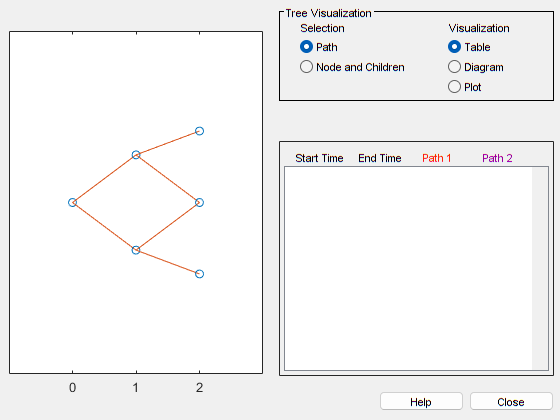

treeviewer(BDDT)